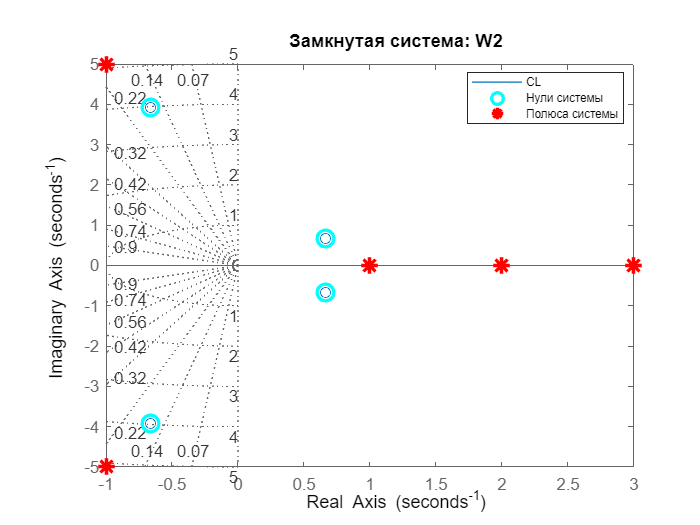

% Параметры варианта
p = 3; % Вещественные полюса
q = 2; % Комплексно-сопряженные полюса
n = 3; % Количество неустойчивых полюсов разомкнутой системы
m = 3; % Количество неустойчивых полюсов замкнутой системы

% 1. Передаточные функции
s = tf('s');
num1 = [-7 18 97 -120 -588];
den1 = [1 -4 1 4 10 -12];
W1 = tf(num1, den1);

num2 = [-12 0 -180 240 -168];
den2 = [1 8 25 40 34 12];
W2 = tf(num2, den2);

num3 = [12 0 180 -240 168];
den3 = [1 -4 25 -140 274 -156];
W3 = tf(num3, den3);


% Замкнутые системы
CL1 = feedback(W1, 1);
CL2 = feedback(W2, 1);
CL3 = feedback(W3, 1);

% 2. Карты нулей и полюсов
figure;
map(W1, CL1, 'W1');

figure;
map(W2, CL2, 'W2');

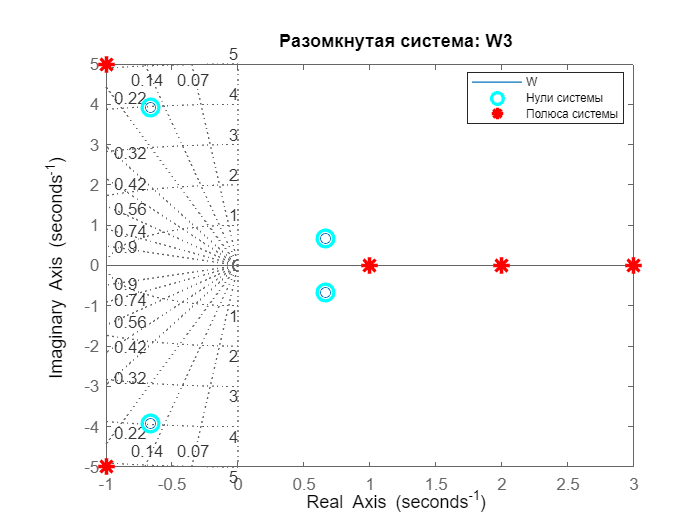

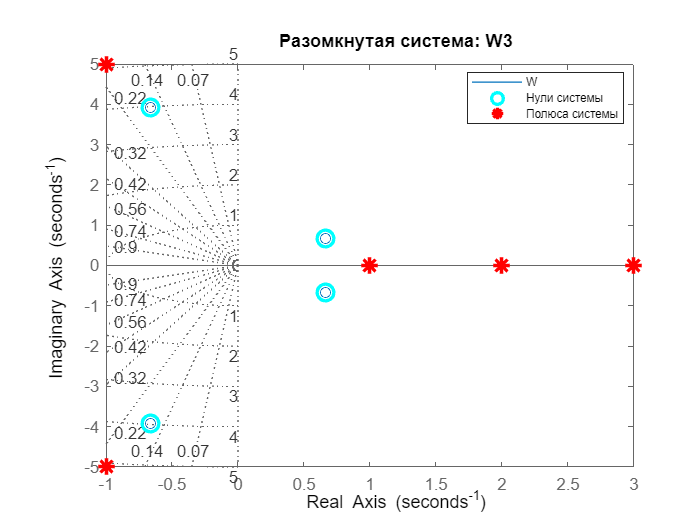

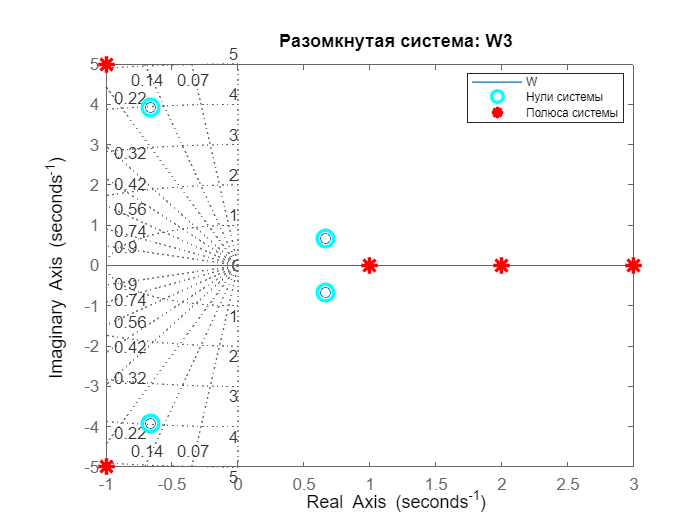

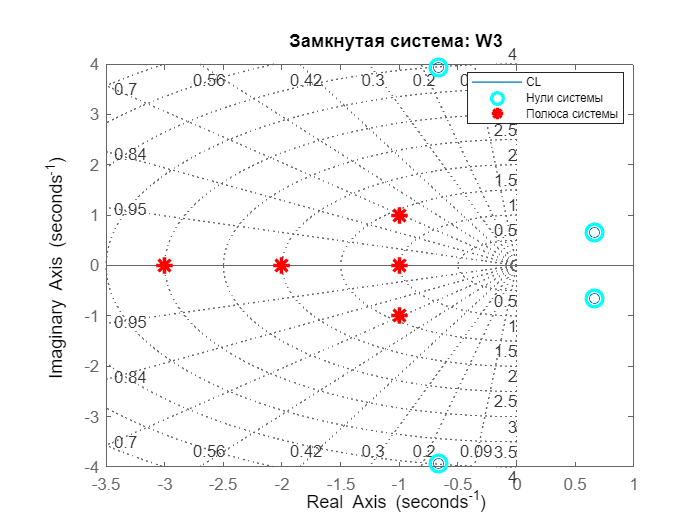


figure;
map(W3, CL3, 'W3');

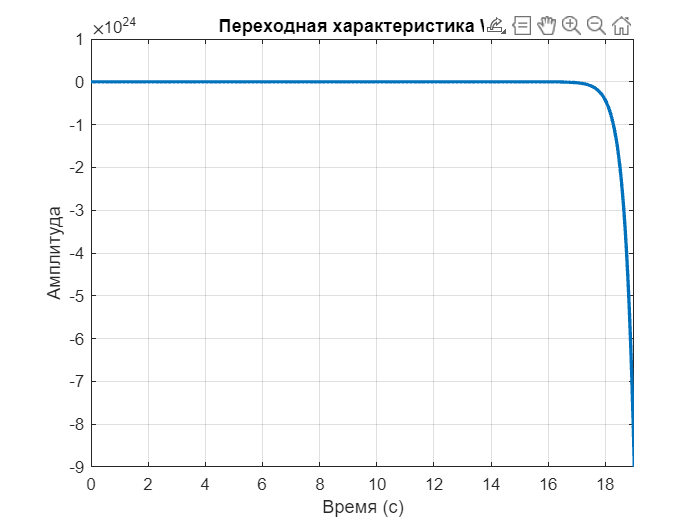


% 3. Переходные характеристики
figure;
transition(W1,'W1')
xlim([0 19])

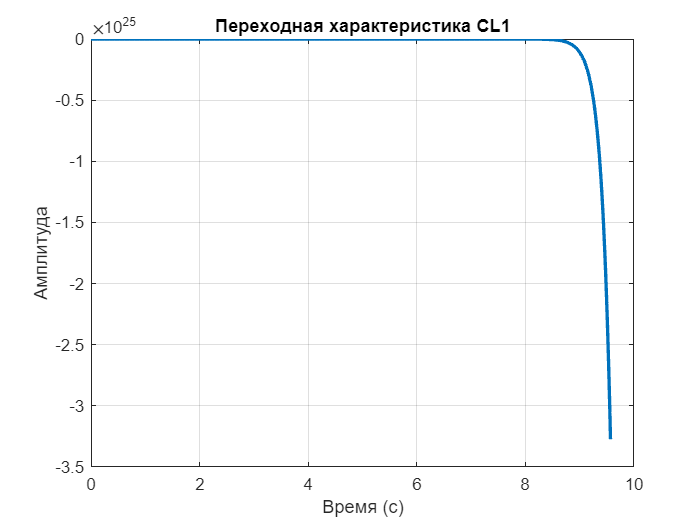

transition(CL1, 'CL1')

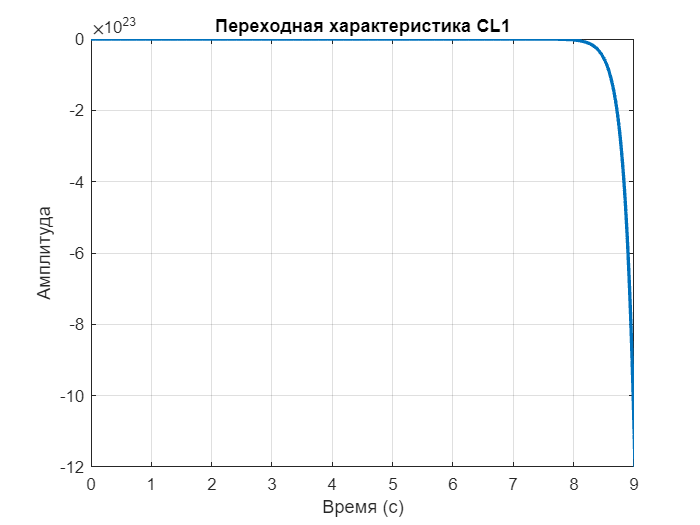

xlim([0 9])

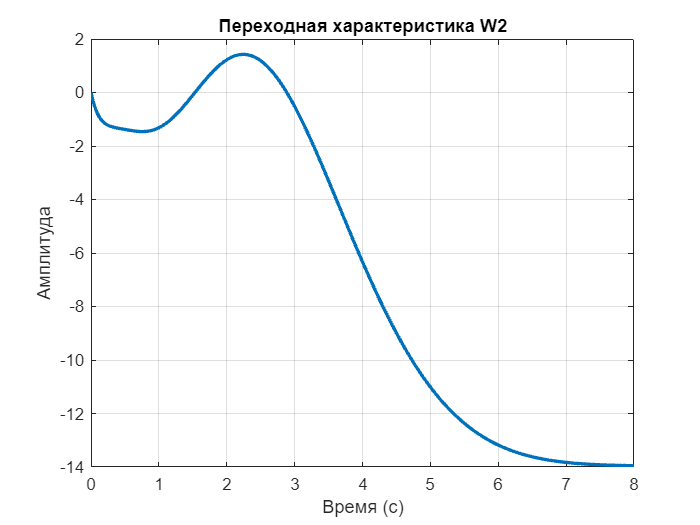


figure;
transition(W2,'W2')
xlim([0 8])

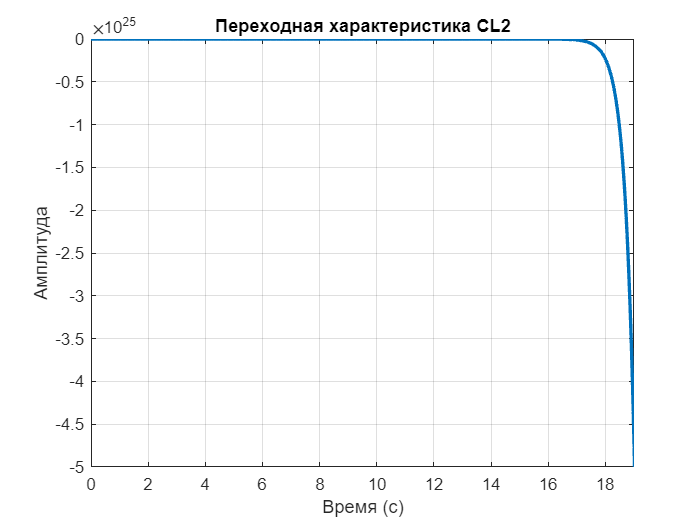

transition(CL2, 'CL2')
xlim([0 19])

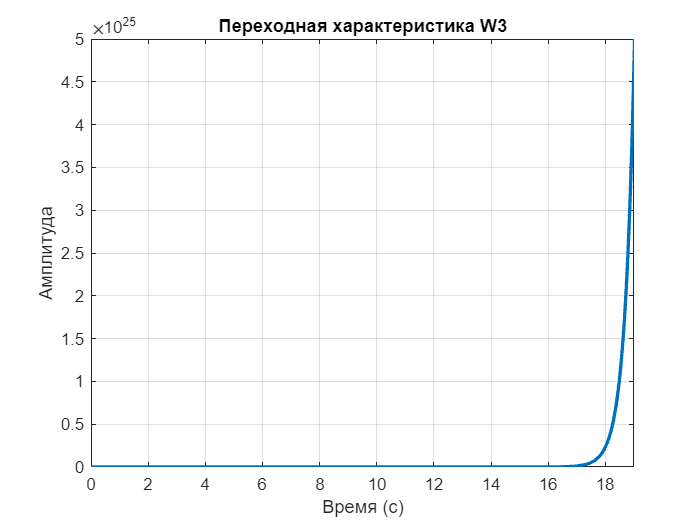


figure;
transition(W3,'W3')
xlim([0 19])

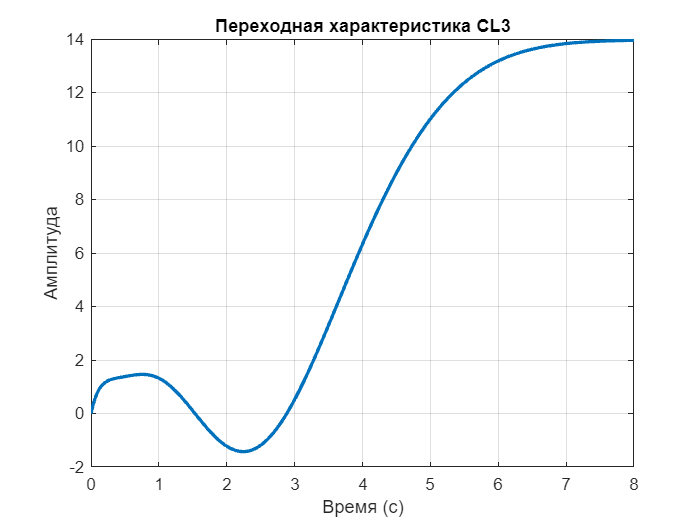

transition(CL3, 'CL3')
xlim([0 8])

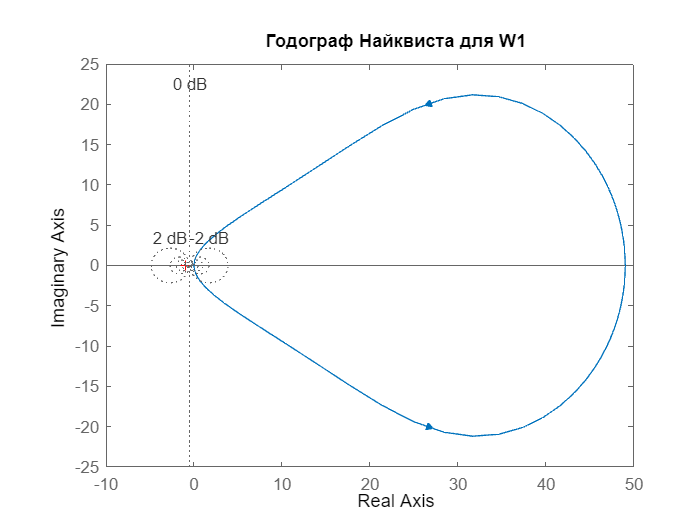



% 4. Годограф Найквиста
figure;
hodograph(W1,'W1');

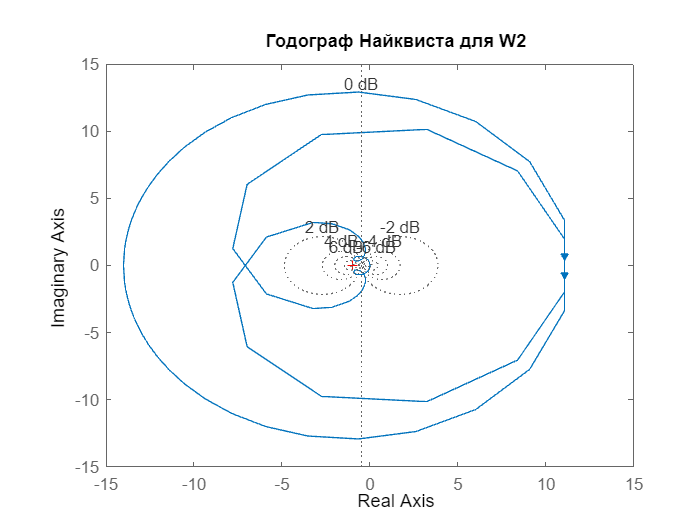


figure;
hodograph(W2,'W2');

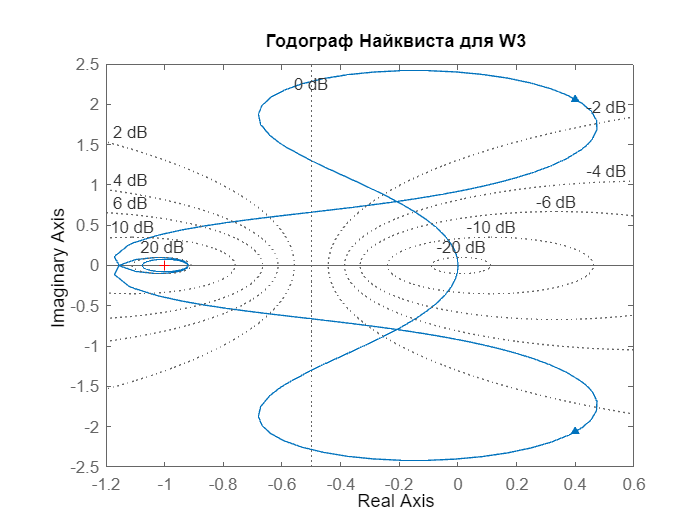


figure;
hodograph(W3,'W3');

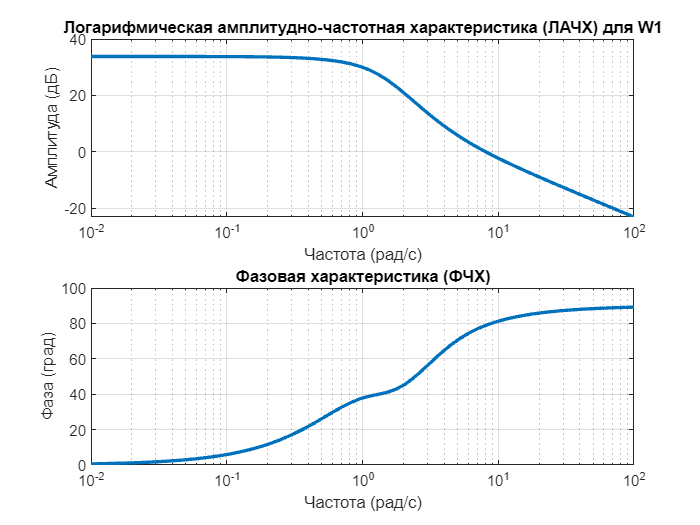


% 5. ЛАФЧХ для проверки устойчивости
figure;
lapfs(W1,'W1');

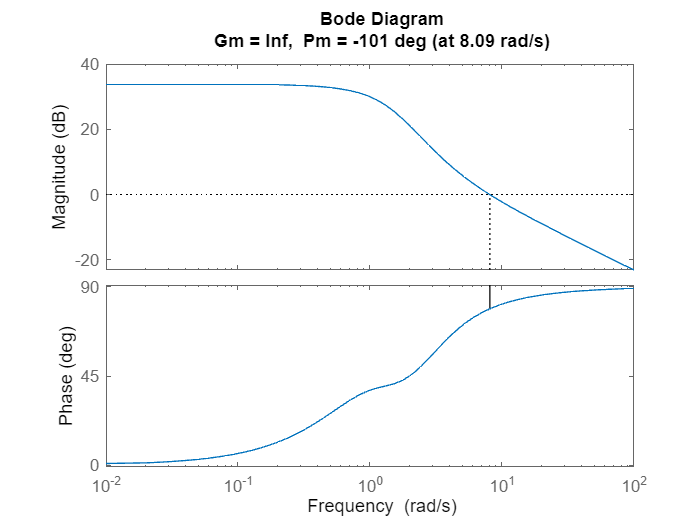

figure;
margin(W1);

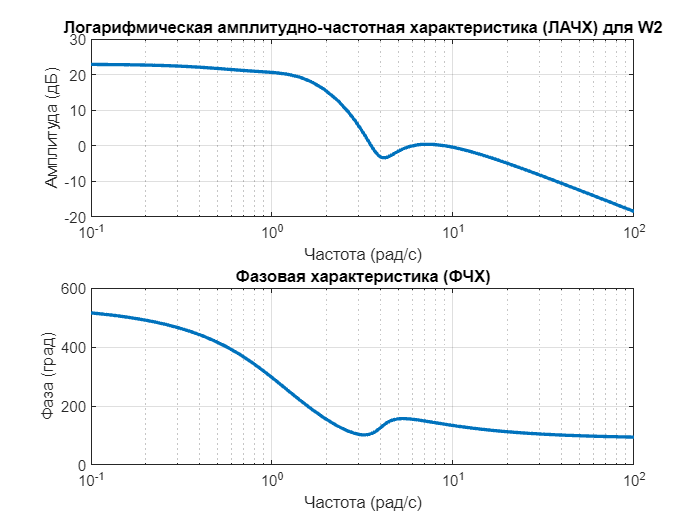

% figure;
% lapfs(CL1,'CL1');

figure;
lapfs(W2,'W2');

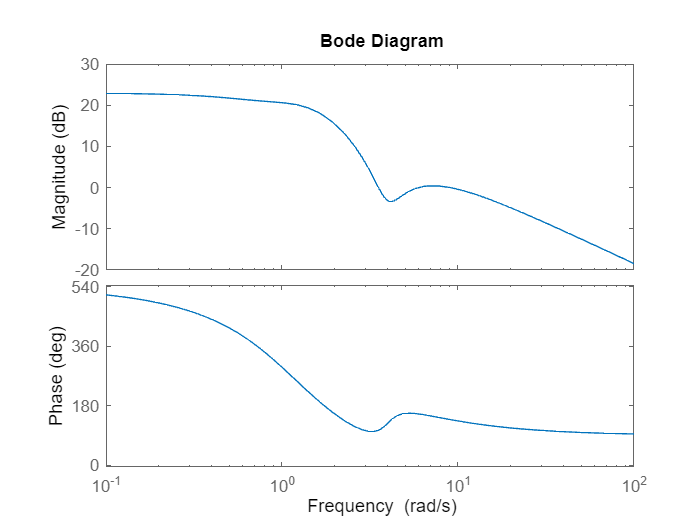

figure;
bode(W2);

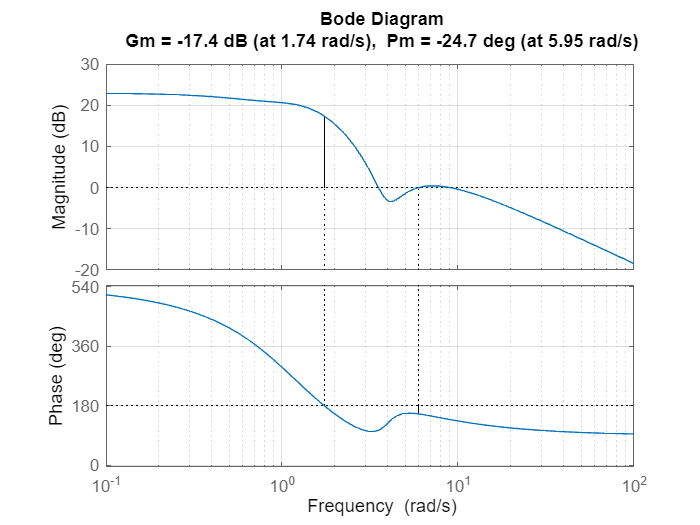

margin(W2);
grid on;

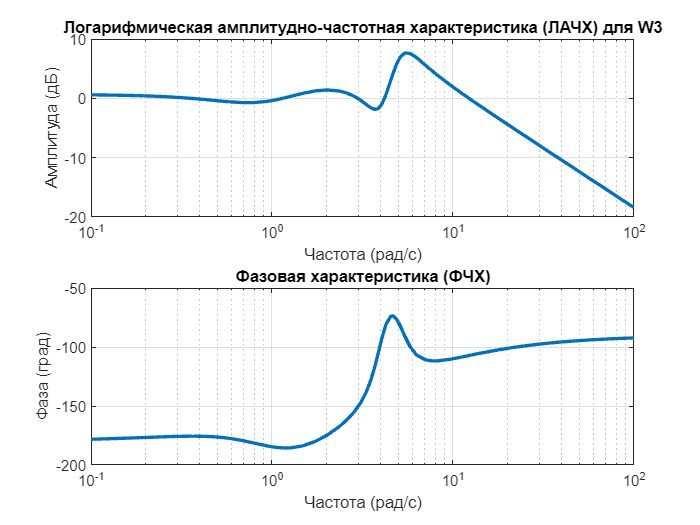

% figure;
% lapfs(CL2,'CL2');

figure;
lapfs(W3,'W3');

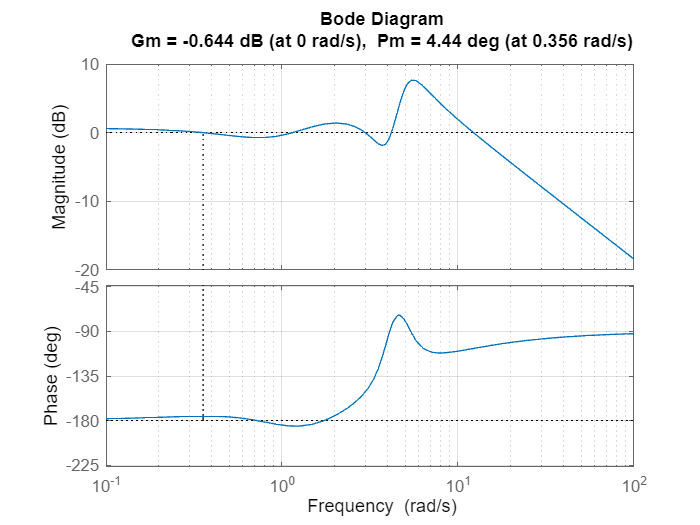

figure;
margin(W3);
grid on;

% figure;
% lapfs(CL3,'CL3');

x = sym('s');
Q1 = expand((x-1)*(x-2)*(x-3)*(x+1-1i)*(x+1+1i))

$$Q1 = s^{5}-4\,s^{4}+s^{3}+4\,s^{2}+10\,s-12$$

D1 = expand((x-4)*(x-5)*(x-6)*(x+2-1i)*(x+2+1i))

$$D1 = s^{5}-11\,s^{4}+19\,s^{3}+101\,s^{2}-110\,s-600$$

R1 = D1 - Q1

$$R1 = -7\,s^{4}+18\,s^{3}+97\,s^{2}-120\,s-588$$


Q2 = expand((x+1)*(x+2)*(x+3)*(x+1-1i)*(x+1+1i))

$$Q2 = s^{5}+8\,s^{4}+25\,s^{3}+40\,s^{2}+34\,s+12$$

D2 = expand((x-1)*(x-2)*(x-3)*(x+1-5i)*(x+1+5i))

$$D2 = s^{5}-4\,s^{4}+25\,s^{3}-140\,s^{2}+274\,s-156$$

R2 = D2 - Q2

$$R2 = -12\,s^{4}-180\,s^{2}+240\,s-168$$


Q3 = expand((x-1)*(x-2)*(x-3)*(x+1-5i)*(x+1+5i))

$$Q3 = s^{5}-4\,s^{4}+25\,s^{3}-140\,s^{2}+274\,s-156$$

D3 = expand((x+1)*(x+2)*(x+3)*(x+1-1i)*(x+1+1i))

$$D3 = s^{5}+8\,s^{4}+25\,s^{3}+40\,s^{2}+34\,s+12$$

R3 = D3 - Q3

$$R3 = 12\,s^{4}+180\,s^{2}-240\,s+168$$

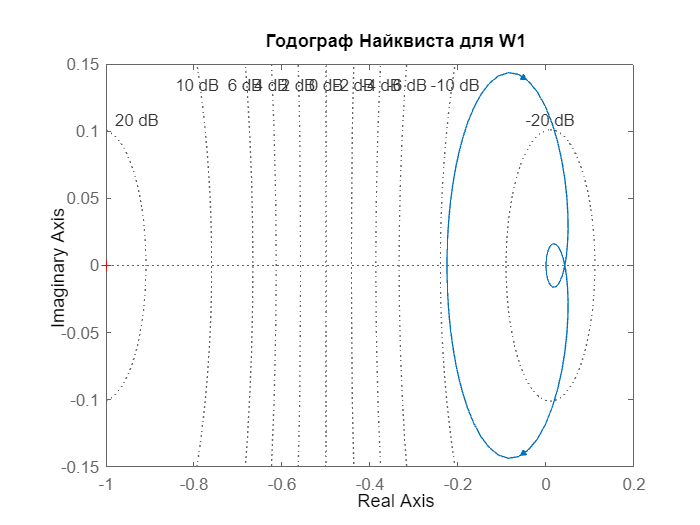

k1 = 0.3;
k2 = 1.5;

num4 = [1 -3];
den4 = [1 7 4];
W4 = k1 * tf(num4, den4);

hodograph(W4, 'W1');

[Gm4, Pm4, Wcg4, Wcp4] = margin(W4)

Gm4 = 4.4444

Pm4 = Inf

Wcg4 = 0

Wcp4 = NaN

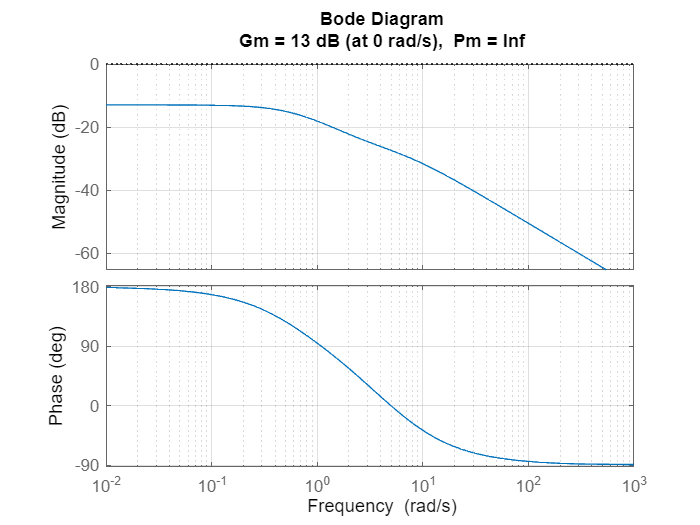

margin(W4);
grid on;

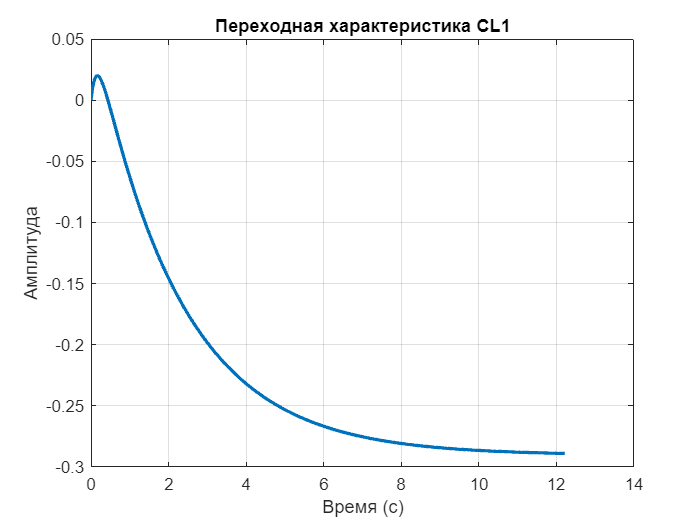


CL4 = feedback(W4, 1);

figure;
transition(CL4, 'CL1');

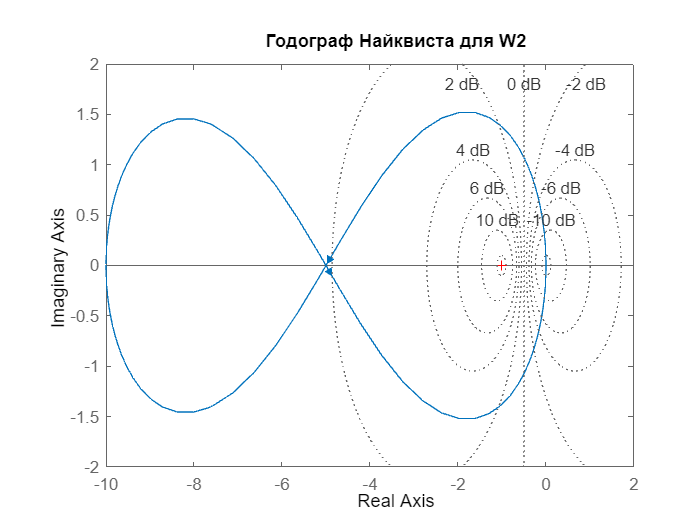



num5 = [100 40 4];
den5 = [100 -15 -8 -0.6];
W5 = k2 * tf(num5, den5);

hodograph(W5, 'W2');

[Gm5, Pm5,  Wcg5, Wcp5] = margin(W5)

Gm5 = 0.2000

Pm5 = 68.9359

Wcg5 = 0.2000

Wcp5 = 1.4662

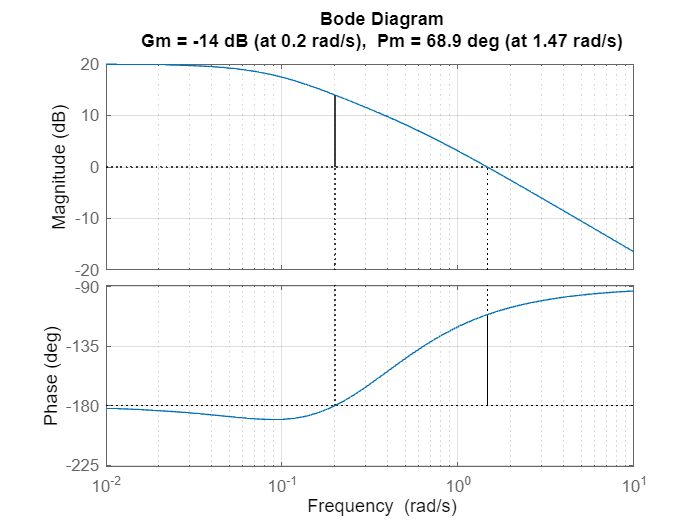

margin(W5);
grid on;

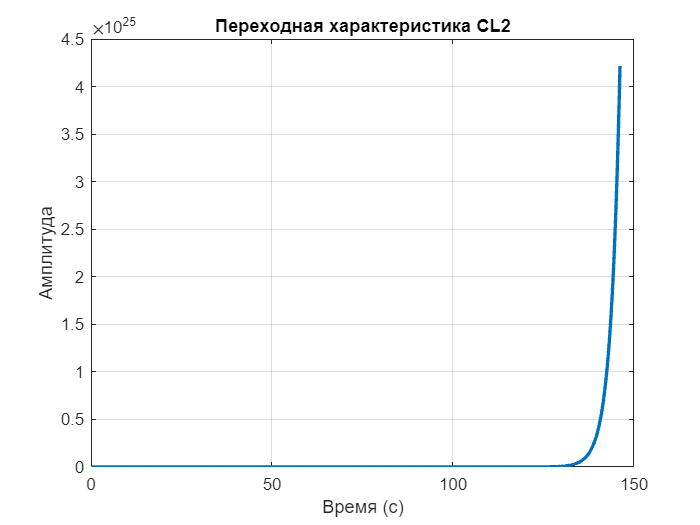


CL5 = feedback(W5, 1);

figure;
transition(W5, 'CL2');

x = sym('w');
z = simplify(expand(((x*1i-3)*(-1*x^2-7*1i*x+4))/((-1*x^2+7*1i*x+4)*(-1*x^2-7*1i*x+4))))

$$z = \frac{-w^{3}\,\mathrm{i}+10\,w^{2}+25\,w\,\mathrm{i}-12}{w^{4}+41\,w^{2}+16}$$

u = (10*x^2 - 12)/(x^4 + 41*x^2 + 16)

$$u = \frac{10\,w^{2}-12}{w^{4}+41\,w^{2}+16}$$

v = (25*x - x^3)/(x^4 + 41*x^2 + 16)

$$v = \frac{25\,w-w^{3}}{w^{4}+41\,w^{2}+16}$$

A = simplify(sqrt(expand(u^2+v^2)))

$$A = \sqrt{\frac{w^{2}+9}{w^{4}+41\,w^{2}+16}}$$

phase_f = atan2(v, u)

$$phase\_f = \text{atan2}\left(\frac{25\,w-w^{3}}{w^{4}+41\,w^{2}+16},\frac{10\,w^{2}-12}{w^{4}+41\,w^{2}+16}\right)$$

equation = atan2(v, u) == -pi

$$equation = \text{atan2}\left(\frac{25\,w-w^{3}}{w^{4}+41\,w^{2}+16},\frac{10\,w^{2}-12}{w^{4}+41\,w^{2}+16}\right)=-\pi$$

solve(25*x - x^3)

$$ans = \left(\begin{array}{c} -5\\ 0\\ 5 \end{array}\right)$$

w = sym('w');
k = sym('k');
a = (expand((3*1i*w+k)*(-2*w^2-3*1i*w+1)))

$$a = k+3\,w\,\mathrm{i}-3\,k\,w\,\mathrm{i}-2\,k\,w^{2}+9\,w^{2}-6\,w^{3}\,\mathrm{i}$$

b = simplify(expand((-2*w^2+3*1i*w+1)*(-2*w^2-3*1i*w+1)))

$$b = 4\,w^{4}+5\,w^{2}+1$$

u = (9*w^2-2*k*w^2+k)/(4*w^4 + 5*w^2 + 1)

$$u = \frac{k-2\,k\,w^{2}+9\,w^{2}}{4\,w^{4}+5\,w^{2}+1}$$

v = (3*w - 3*k*w - 6*w^3)/(4*w^4 + 5*w^2 + 1)

$$v = -\frac{3\,k\,w-3\,w+6\,w^{3}}{4\,w^{4}+5\,w^{2}+1}$$

A = simplify(sqrt(expand(u^2+v^2)))

$$A = \sqrt{\frac{k^{2}+9\,w^{2}}{4\,w^{4}+5\,w^{2}+1}}$$

equation = atan2(v, u) == -pi

$$equation = \text{atan2}\left(-\frac{3\,k\,w-3\,w+6\,w^{3}}{4\,w^{4}+5\,w^{2}+1},\frac{k-2\,k\,w^{2}+9\,w^{2}}{4\,w^{4}+5\,w^{2}+1}\right)=-\pi$$

solve(3*w - 3*k*w - 6*w^3)

$$ans = \left(\begin{array}{c} 0\\ -\frac{\sqrt{2}\,\sqrt{1-k}}{2}\\ \frac{\sqrt{2}\,\sqrt{1-k}}{2} \end{array}\right)$$

equation2 = A == 1

$$equation2 = \sqrt{\frac{k^{2}+9\,w^{2}}{4\,w^{4}+5\,w^{2}+1}}=1$$

solve(equation2)

$$ans = \left(\begin{array}{c} -\frac{\sqrt{2}\,\sqrt{1-k}}{2}\\ \frac{\sqrt{2}\,\sqrt{1-k}}{2}\\ -\frac{\sqrt{2}\,\sqrt{k+1}}{2}\\ \frac{\sqrt{2}\,\sqrt{k+1}}{2} \end{array}\right)$$

num4 = [3 2];
den4 = [2 3 1];
W4 = tf(num4, den4);
[Gm4, Pm4, Wcg4, Wcp4] = margin(W4)

Gm4 = Inf

Pm4 = 122.8784

Wcg4 = NaN

Wcp4 = 1.2247

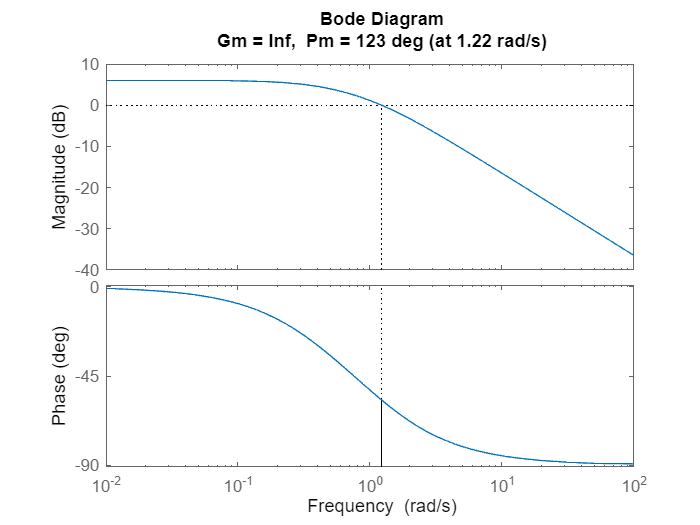

margin(W4);

x = sym('w');
z = simplify(expand(((-100*x^2+40*1i*x+4)*(100*x^3*1i+15*x^2+8*1i*x-0.6))/((-100*x^3*1i+15*x^2-8*1i*x-0.6)*(100*x^3*1i+15*x^2+8*1i*x-0.6))))

$$z = \frac{20\,{\left(1+5\,w\,\mathrm{i}\right)}^{2}\,\left(500\,w^{3}\,\mathrm{i}+75\,w^{2}+40\,w\,\mathrm{i}-3\right)}{250000\,w^{6}+45625\,w^{4}+1150\,w^{2}+9}$$

z1 = expand(z)

$$z1 = \begin{array}{l} \frac{200\,w\,\mathrm{i}}{\sigma_{1}}-\frac{60}{\sigma_{1}}-\frac{5000\,w^{2}}{\sigma_{1}}+\frac{5000\,w^{3}\,\mathrm{i}}{\sigma_{1}}-\frac{137500\,w^{4}}{\sigma_{1}}-\frac{250000\,w^{5}\,\mathrm{i}}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=250000\,w^{6}+45625\,w^{4}+1150\,w^{2}+9 \end{array}$$

u = (-137500*x^4-5000*x^2-60)/(250000*x^6+45625*x^4 + 1150*x^2 + 9)

$$u = -\frac{137500\,w^{4}+5000\,w^{2}+60}{250000\,w^{6}+45625\,w^{4}+1150\,w^{2}+9}$$

v = (-250000*x^5+5000*x^3+200*x)/(250000*x^6+45625*x^4 + 1150*x^2 + 9)

$$v = \frac{-250000\,w^{5}+5000\,w^{3}+200\,w}{250000\,w^{6}+45625\,w^{4}+1150\,w^{2}+9}$$

A = simplify(sqrt(expand(u^2+v^2)))

$$A = \frac{20\,\left(25\,w^{2}+1\right)}{\sqrt{250000\,w^{6}+45625\,w^{4}+1150\,w^{2}+9}}$$

phase_f = atan2(v, u)

$$phase\_f = \text{atan2}\left(\frac{-250000\,w^{5}+5000\,w^{3}+200\,w}{250000\,w^{6}+45625\,w^{4}+1150\,w^{2}+9},-\frac{137500\,w^{4}+5000\,w^{2}+60}{250000\,w^{6}+45625\,w^{4}+1150\,w^{2}+9}\right)$$

subs(phase_f, w, 0)

$$ans = \pi$$

double(ans)

ans = 3.1416

equation = atan2(v, u) == -pi

$$equation = \text{atan2}\left(\frac{-250000\,w^{5}+5000\,w^{3}+200\,w}{250000\,w^{6}+45625\,w^{4}+1150\,w^{2}+9},-\frac{137500\,w^{4}+5000\,w^{2}+60}{250000\,w^{6}+45625\,w^{4}+1150\,w^{2}+9}\right)=-\pi$$

solve(-250000*x^5+5000*x^3+200*x)

$$ans = \left(\begin{array}{c} -\frac{1}{5}\\ 0\\ \frac{1}{5} \end{array}\right)$$

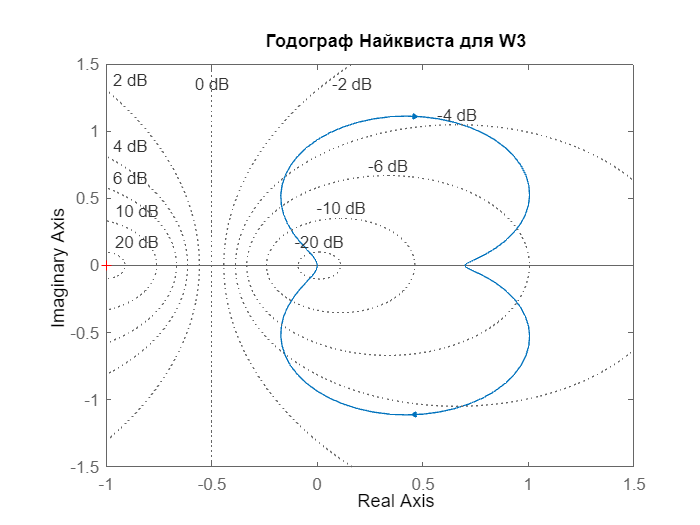

tau1 = 0;


num4 = [1 7];
den4 = [1 2 10];
W4 = tf(num4, den4, 'InputDelay', tau1);

hodograph(W4, 'W3');

[Gm4, Pm4, Wcg4, Wcp4] = margin(W4)

Gm4 = Inf

Pm4 = 94.1299

Wcg4 = NaN

Wcp4 = 3.6202

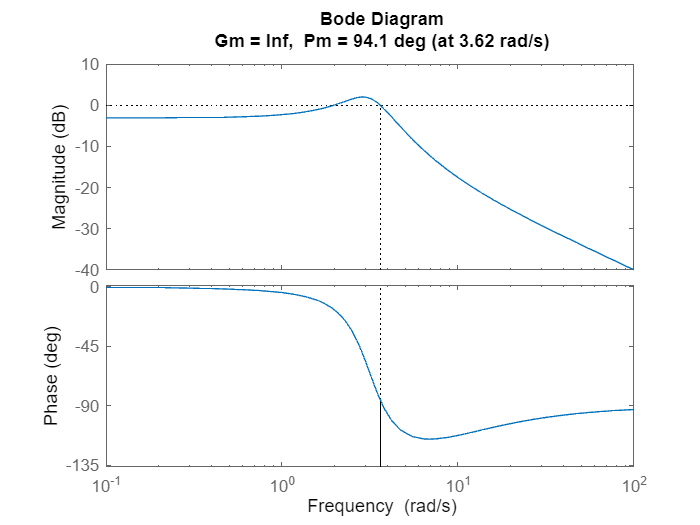

margin(W4);

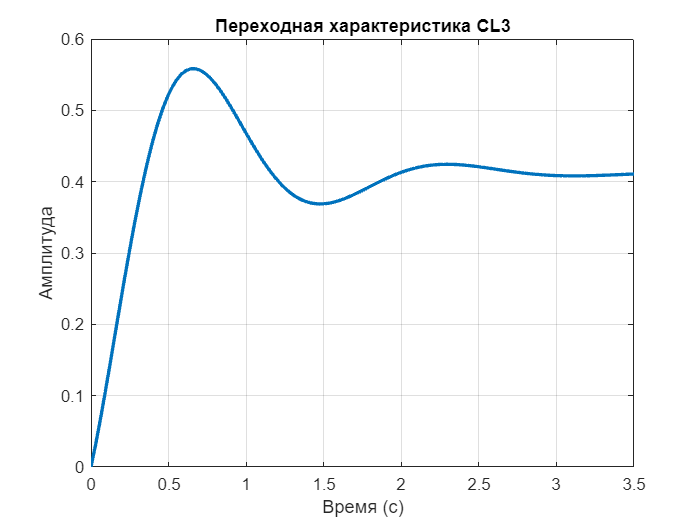


CL4 = feedback(W4, 1);

figure;
transition(CL4, 'CL3');

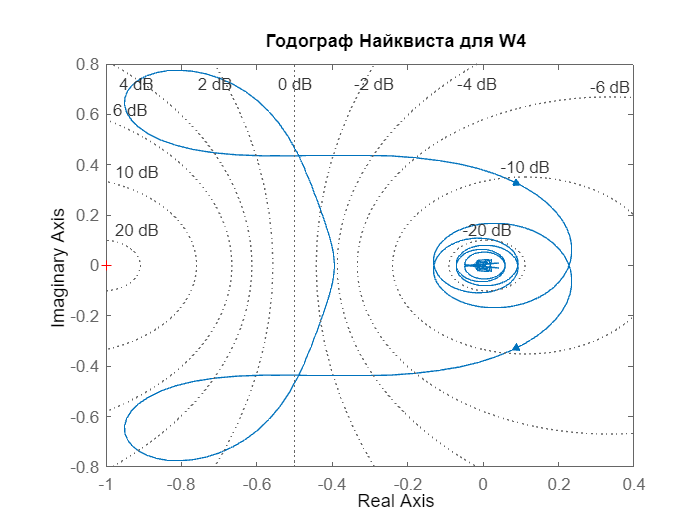


tau2 = 1;
num5 = [10 -5 -15];
den5 = [10 5 10 38];
W5 = tf(num5, den5, 'InputDelay', tau2);

hodograph(W5, 'W4');

[Gm5, Pm5,  Wcg5, Wcp5] = margin(W5)

Gm5 = 2.5333

Pm5 = -30.2760

Wcg5 = 0

Wcp5 = 1.8660

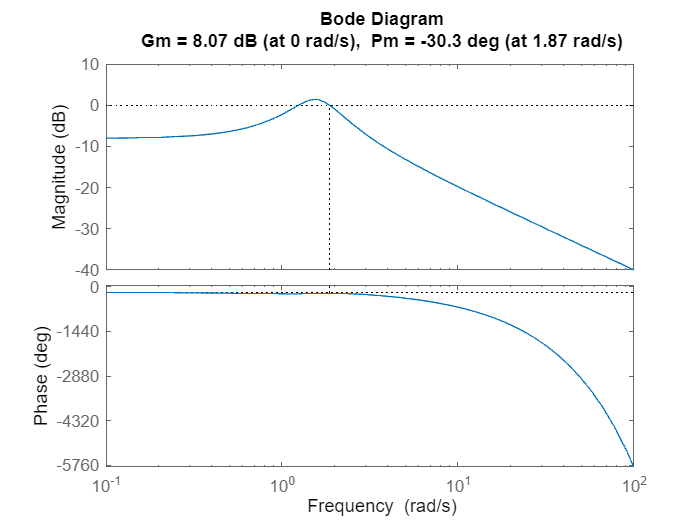

margin(W5);

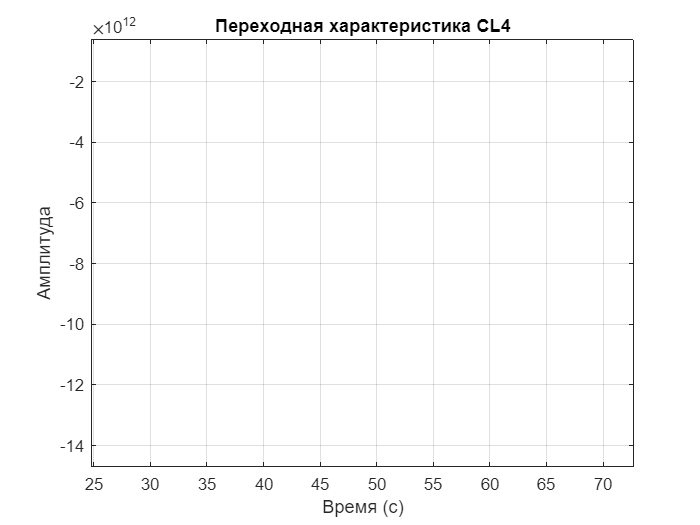


CL5 = feedback(W5, 1);

figure;
transition(CL5, 'CL4');
xlim([0 85])

x = sym('w')

$$x = w$$

u = (-5*x^2+70)/(x^4-16*x^2+100)

$$u = -\frac{5\,w^{2}-70}{w^{4}-16\,w^{2}+100}$$

v = (-x^3-4*x)/(x^4-16*x^2+100)

$$v = -\frac{w^{3}+4\,w}{w^{4}-16\,w^{2}+100}$$

A = simplify(sqrt(expand(u^2+v^2)))

$$A = \sqrt{\frac{w^{2}+49}{w^{4}-16\,w^{2}+100}}$$

simplify(solve(A == 1))

$$ans = \left(\begin{array}{c} -\frac{\sqrt{2}\,\sqrt{17-\sqrt{85}}}{2}\\ \frac{\sqrt{2}\,\sqrt{17-\sqrt{85}}}{2}\\ -\frac{\sqrt{2}\,\sqrt{\sqrt{85}+17}}{2}\\ \frac{\sqrt{2}\,\sqrt{\sqrt{85}+17}}{2} \end{array}\right)$$

phi = atan2((-x^3-4*x)/(x^4-16*x^2+100), (-5*x^2+70)/(x^4-16*x^2+100))

$$phi = \text{atan2}\left(-\frac{w^{3}+4\,w}{w^{4}-16\,w^{2}+100},-\frac{5\,w^{2}-70}{w^{4}-16\,w^{2}+100}\right)$$

a = (sqrt((2))*sqrt(17 - sqrt(85)))/2

a = 1.9724

b = (sqrt((2))*sqrt(17 + sqrt(85)))/2

b = 3.6207

c = -(sqrt((2))*sqrt(17 - sqrt(85)))/2

c = -1.9724

d = -(sqrt((2))*sqrt(17 + sqrt(85)))/2

d = -3.6207

phi1 = atan2((-a^3-4*a)/(a^4-16*a^2+100), (-5*a^2+70)/(a^4-16*a^2+100))

phi1 = -0.2987

phi2 = atan2((-b^3-4*b)/(b^4-16*b^2+100), (-5*b^2+70)/(b^4-16*b^2+100))

phi2 = -1.4991

phi3 = atan2((-c^3-4*c)/(c^4-16*c^2+100), (-5*c^2+70)/(c^4-16*c^2+100))

phi3 = 0.2987

phi4 = atan2((-d^3-4*d)/(d^4-16*d^2+100), (-5*d^2+70)/(d^4-16*d^2+100))

phi4 = 1.4991

s = tf('s');
W3 = (s + 7) / (s^2 + 2*s + 10);
W4 = (10*s^2 - 5*s - 15) / (10*s^3 + 5*s^2 + 10*s + 38);

tau_values = linspace(0, 3, 10000);
order_pade = 5;

tau_stability_W3 = [];
tau_stability_W4 = [];

for tau = tau_values

    delay_pade = pade(exp(-tau * s), order_pade);
    
    W3_delayed = W3 * delay_pade;
    W4_delayed = W4 * delay_pade;
    
    CL3 = feedback(W3_delayed, 1);
    CL4 = feedback(W4_delayed, 1);
    
    is_stable_W3 = isstable(CL3);
    is_stable_W4 = isstable(CL4);
    
    if is_stable_W3
        tau_stability_W3 = [tau_stability_W3, tau];
    end
    if is_stable_W4
        tau_stability_W4 = [tau_stability_W4, tau];
    end
end

if ~isempty(tau_stability_W3)
    fprintf('Пределы устойчивости W3: τ ∈ [%.3f, %.3f]\n', min(tau_stability_W3), max(tau_stability_W3));
else
    disp('Система W3 неустойчива для всех значений τ.');
end

Пределы устойчивости W3: τ ∈ [0.000, 2.236]



if ~isempty(tau_stability_W4)
    fprintf('Пределы устойчивости W4: τ ∈ [%.3f, %.3f]\n', min(tau_stability_W4), max(tau_stability_W4));
else
    disp('Система W4 неустойчива для всех значений τ.');
end

Пределы устойчивости W4: τ ∈ [0.338, 0.717]


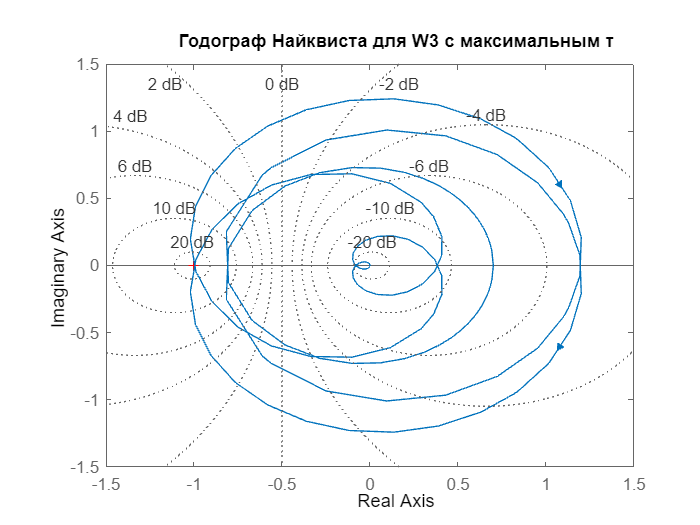


if ~isempty(tau_stability_W3)
    figure;
    delay_pade = pade(exp(-max(tau_stability_W3) * s), order_pade);
    W3_delayed = W3 * delay_pade;
    nyquist(W3_delayed);
    title('Годограф Найквиста для W3 с максимальным τ');
    grid on;
end

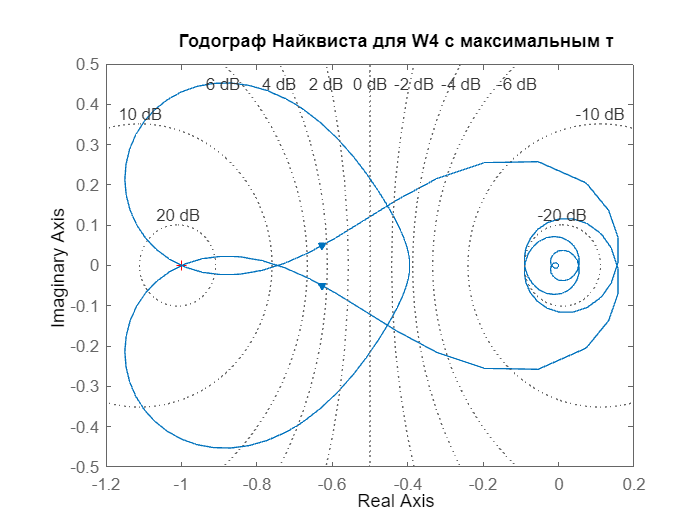


if ~isempty(tau_stability_W4)
    figure;
    delay_pade = pade(exp(-max(tau_stability_W4) * s), order_pade);
    W4_delayed = W4 * delay_pade;
    nyquist(W4_delayed);
    title('Годограф Найквиста для W4 с максимальным τ');
    grid on;
end

function map(W, CL, name)
    % Карты для разомкнутой системы
    figure
    pzmap(W);
    title(['Разомкнутая система: ', name]);
    grid on;
    hold on;
    [z, p] = zpkdata(W, 'v');
    plot(real(z), imag(z), 'co', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Нули системы'); % Зелёные нули
    plot(real(p), imag(p), 'r*', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Полюса системы'); % Красные полюса
    legend('FontSize', 7, 'Location', 'best');
    hold off;

    figure
    pzmap(CL);
    title(['Замкнутая система: ', name]);
    grid on;
    hold on;
    [z_cl, p_cl] = zpkdata(CL, 'v');
    plot(real(z_cl), imag(z_cl), 'co', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Нули системы'); % Зелёные нули
    plot(real(p_cl), imag(p_cl), 'r*', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Полюса системы'); % Красные полюса
    legend('FontSize', 7, 'Location', 'best');
    hold off;
end

function transition(W,a)
[step_y, step_t] = step(W);
plot(step_t, step_y, 'LineWidth', 2);
h='Переходная характеристика '+string(a);
title(h);
xlabel('Время (с)');
ylabel('Амплитуда');
grid on;
end

function hodograph(W,a)
nyquist(W);
h='Годограф Найквиста для '+string(a);
title(h);
grid on;
end

function lapfs(W,a)

[mag, phase, omega] = bode(W);
mag = squeeze(mag);
phase = squeeze(phase);

subplot(2,1,1);
semilogx(omega, 20*log10(mag), 'LineWidth', 2);
h='Логарифмическая амплитудно-частотная характеристика (ЛАЧХ) для '+string(a);
title(h);
xlabel('Частота (рад/с)');
ylabel('Амплитуда (дБ)');
grid on;

subplot(2,1,2);
semilogx(omega, phase, 'LineWidth', 2);
title('Фазовая характеристика (ФЧХ)');
xlabel('Частота (рад/с)');
ylabel('Фаза (град)');
grid on;
end
